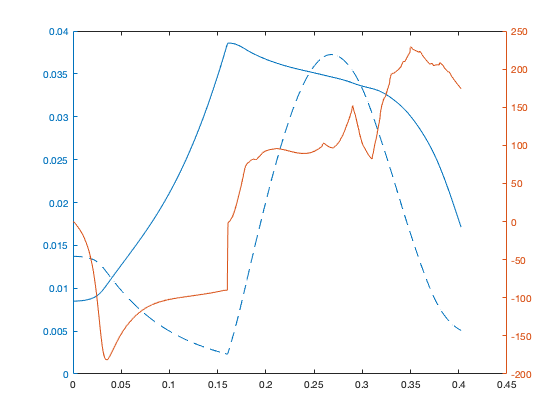

Fmax = 5500; %最大筋力
Lopt = 0.055; %収縮要素の至適長
Lslack = 0.42; %弾性要素の自然長
mass = 70.0; %体重
Lcc0 = Lopt*0.7;

width = 0.888;
c = -1/width^2;
Fiso0 = c*(Lcc0/Lopt)^2 - 2*c*Lcc0/Lopt + c + 1;

opts = odeset('RelTol', 1e-5, 'AbsTol', 1e-8, 'Event', 'dynEventFcn');
    %相対許容誤差を1e-5に抑える
    %x=0(離地)になった瞬間に計算終了

q0 = 2*mass*98/(Fmax*Fiso0);

Ksec = zeros(31,1);
motiontime = zeros(31,1);
avePower = zeros(31,1);
for k = 1:31
    Ksec(k) = (0.9+0.1*k)*10^5;
    ACTgene = ACT(k,:);
    Lsec0 = Lslack + 2*mass*9.8 / Ksec(k);
    [t,y] = ode45(@(t,y) dynamics(t,y,ACTgene,Fmax,Lopt,Lslack,Ksec(k),mass),...
        [0,0.5], [0;-1e-10;2*mass*9.8/(Fmax*Fiso0);Lcc0; Lsec0], opts);
    motiontime(k) = t(end);
    Power = -Ksec(k).*(y(2:end,5)-Lslack).*diff(y(:,4))./diff(t);
    avePower(k) = sum(Power.*diff(t));
    if k==1
        yyaxis left
        plot(t,y(:,4)-0.03)
        hold on
        plot(t,y(:,5)-0.42)
        yyaxis right
        plot(t,[0;Power])
    end
    %avePower(k) = sum(-Ksec(k).*(y(2:end,5)-Lslack).*diff(y(:,4)));
    %avePower(k) = (2*mass*y(end,1)^2-Ksec(k)*(y(end,5)-Lslack)^2/2)/motiontime(k);
end

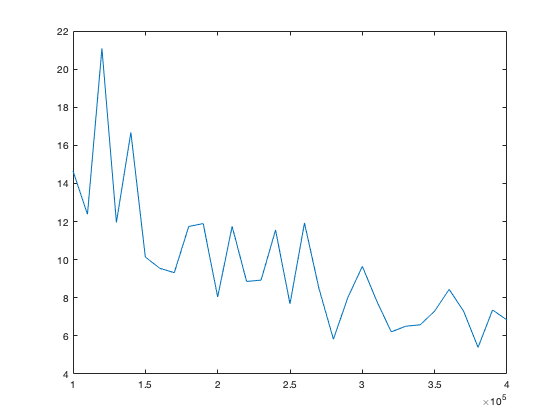

figure;
plot(Ksec,avePower)

%hold on
%f = fit(Ksec, motiontime, 'power2');
%pow_fit = f.a*Ksec.^f.b + f.c;
%plot(Ksec,pow_fit)